**Create the shape**

model = createpde(1);
importGeometry(model,"STL's\Tempel 1 DeepImpact Stardust.stl");
generateMesh(model)

ans =   FEMesh with properties:

             Nodes: [3×22092 double]
          Elements: [10×14759 double]
    MaxElementSize: 0.4076
    MinElementSize: 0.2038
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


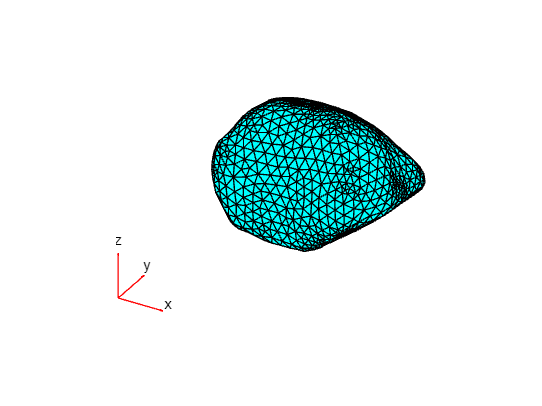

% pdeplot3D(model)

**Setup**

po = [0 0 0]; % point of our plane, here simply the origin
no = [0 1 0]; % normal vector of the plane i.e. pointing along the y-axis
num = 1000;
trials = 1;
areas = zeros(num,1,'double');
results = zeros(trials,3,'double');
g = [0 0 0];
beta = 0;

**Get a random uniform sample of *****num***** points on a sphere. **(https://uk.mathworks.com/matlabcentral/fileexchange/37004-suite-of-functions-to-perform-uniform-sampling-of-a-sphere)

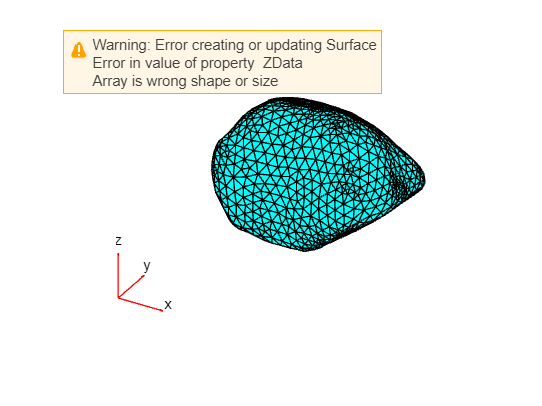

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [0 0.2467 0.1645 0.0722 0.1401 0.1315 1.3109 1.0721 0.9461 0.9539 0.8344 0.8388 0.5393 0.1251 0.4406 0.1223 -0.0423 -0.0895 -0.0764 -0.0684 -0.0817 -0.5087 -0.1603 -2.3754 -0.3562 -0.2690 -0.4407 -2.5222 -0.1671 -0.0836 -0.2459 … ]
           YData: [0 0.1203 0.0803 0.0564 0.1176 0.1270 2.9443 2.9456 2.9117 2.9357 2.9099 2.9253 2.1630 0.5018 2.0731 0.5754 1.2110 1.2800 0.7267 0.6512 0.5812 2.3931 0.0853 0.5049 -0.0628 -0.0474 -0.0937 -0.9180 -0.0744 -0.0372 -0.1199 -0.0968 … ]
           ZData: [2.6303 2.6117 2.6180 2.6224 2.6163 2.6149 -0.9242 -0.8989 -1.1143 -0.8851 -0.9836 -0.8726 -1.8705 2.4330 -1.9083 2.3594 1.9391 1.9023 2.2490 2.2834 2.3538 -1.6502 2.5970 2.0378 2.5739 2.5984 2.5549 2.0970 2.6152 2.6220 2.6032 … ]
           

tic
s = surface(model.Mesh.Nodes(1,:), model.Mesh.Nodes(2,:), model.Mesh.Nodes(3,:))

for j=1:1:trials
    V=RandSampleSphere(num,'stratified');

**Run the pyramid rotation using the previously acquired points on a sphere.**

    for k = 1:length(V)

**Get x-z projection of the shapegss**

        %get data as a result of rotation
        XX = model.Mesh.Nodes(1,:);
        YY = model.Mesh.Nodes(2,:);
        ZZ = model.Mesh.Nodes(3,:);
        % concat the shape grid
        gr = [XX(:) YY(:) ZZ(:)];
        v = gr - repmat(po,numel(XX(:)),1);
        % dot vector with the normal vector of the plane of intrest
        % this represents the distance from the grid points to our plane along the normal
        d = v(:,1)*no(1) + v(:,2)*no(2) + v(:,3)*no(3); 
        % get the projected points
        projected_grid = gr - d .* repmat(no,numel(XX(:)),1);
        projected_grid = unique(projected_grid,'rows','stable');
        %we need the outer points of the region, acquire this and the area of
        %the region with convex hull.
        [shadow,ar] = convhull(projected_grid(:,1),projected_grid(:,3));
        areas(k) = ar;          

**Rotate the shape**

        a = [V(k,1), V(k,2), 0];
        b = [0 0 2];
        if norm(g)==0; g = cross(a,b); continue; end %if the magnitude of the cross product is zero, then continue to the next iteration
        rotate(s,rad2deg(beta),[0 0 0],g);
        g = 2*cross(a,b); %find the cross product between a and b
        beta = acos(V(k,3));        
        rotate(s,-rad2deg(beta),[0 0 0],g);
%         pdegplot(s)
%         drawnow
    end
    results(j,1) = surfaceArea(alphaShape(model.Mesh.Nodes'));
    results(j,2) = mean(areas);
    results(j,3) = toc;
end

Unrecognized function or variable 'u'.

Error in rotate (line 51)
x = u(1);

results
